%% Load Sample Frames
clear all;

I = imread ('rec1.jpg')

I = 3280×4928×3 uint8 array
I(:,:,1) =

  Columns 1 through 1,666

   198   197   197   196   196   195   195   195   194   196   195   196   195   195   195   195   196   194   194   195   195   195   195   196   196   195   194   193   194   196   195   194   194   194   194   195   195   195   195   195   196   196   195   195   195   195   196   196   196   195   195   195   193   194   193   193   193   193   195   196   196   195   195   196   196   196   195   195   196   196   197   196   196   197   197   197   197   197   196   196   195   195   195   195   196   196   193   193   194   194   196   196   196   196   194   194   193   194   194   194   196   196   196   196   196   196   197   198   197   197   196   196   197   196   197   197   196   196   196   196   196   197   198   197   196   197   197   198   197   197   196   195   196   197   197   197   197   197   195   195   196   196   195   196   196   196   195   196   196   195   195   195   197   197   196   

subplot(1,2,1)
imshow(I)
title('Pic')

grayFrame = im2gray(I)

grayFrame = 3280×4928 uint8 matrix
   195   194   194   193   193   192   192   192   191   193   192   193   192   192   192   192   193   191   191   192   192   192   192   193   193   192   191   190   191   193   192   191   191   191   191   192   192   192   192   192   193   193   192   192   192   192   193   193   193   192
   193   192   192   192   193   192   192   191   191   192   192   193   192   192   192   193   193   192   192   192   192   192   192   192   193   191   190   191   192   193   192   193   193   192   191   192   192   192   192   192   193   193   191   192   193   193   193   193   193   193
   192   191   192   192   192   192   192   192   192   193   193   193   193   192   192   193   193   193   193   193   192   192   192   192   192   192   192   192   192   193   193   193   193   192   192   192   192   192   192   192   192   192   192   192   193   193   193   193   193   193
   193   193   193   192   191   191   192   193   193   193  

subplot(1,2,2)
imshow(grayFrame)
title('Grayscale Frame')


features = detectMinEigenFeatures(grayFrame);
subplot(1,2,1)
imshow(I)
hold on
plot(features)
title('Showing All Features')

specFeatures = selectStrongest(features,1000)

specFeatures =   1000×1 cornerPoints array with properties:

    Location: [1000×2 single]
      Metric: [1000×1 single]
       Count: 1000


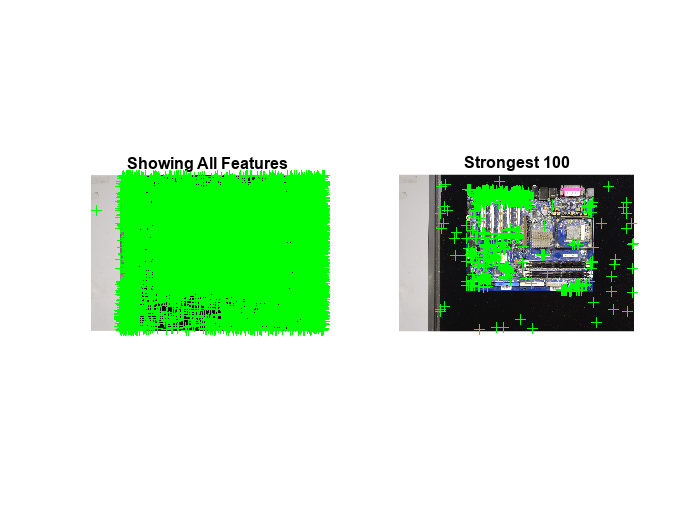

subplot(1,2,2)
imshow(I)
hold on
plot(specFeatures)
title('Strongest 100')